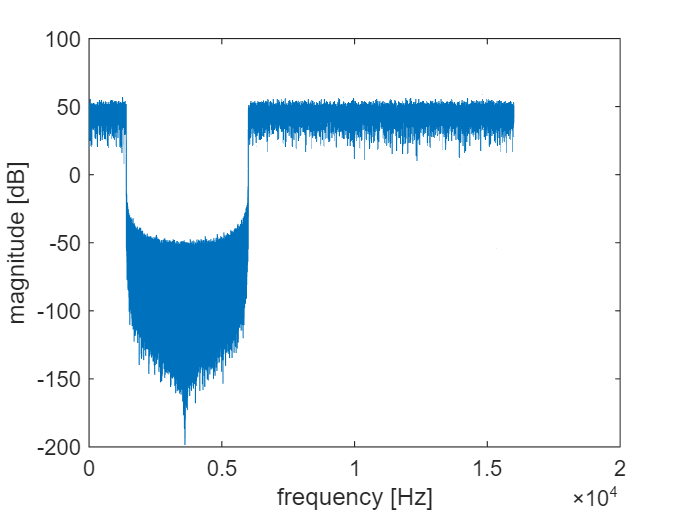

clear all
duration = 3;
fs = 16000;
N = duration*fs; %dit is ook de filter order in fir1
sig = wgn(N,1,0);

%lower cutoff frequency w1 and higher cutoff frequency w2
w1 = 700/fs;
w2 = 3000/fs;

filter = fir1(N,[w1 w2],'stop');

%filterdft = abs(fft(filter));%maar de helft nodig
%filterdft = filterdft(1:floor(N/2+1))

%plot(0:2*fs/N:fs,filterdft)

tot1 = conv(sig,filter); %tijdsdomein

freq_totdft1 = fft(tot1);
freq_totdft1 = freq_totdft1(1:floor(N/2+1));
magn1 = abs(freq_totdft1);

figure;
title('filtered signal')
plot((0:2*fs/N:fs),mag2db(magn1))
ylabel('magnitude [dB]')
xlabel('frequency [Hz]')

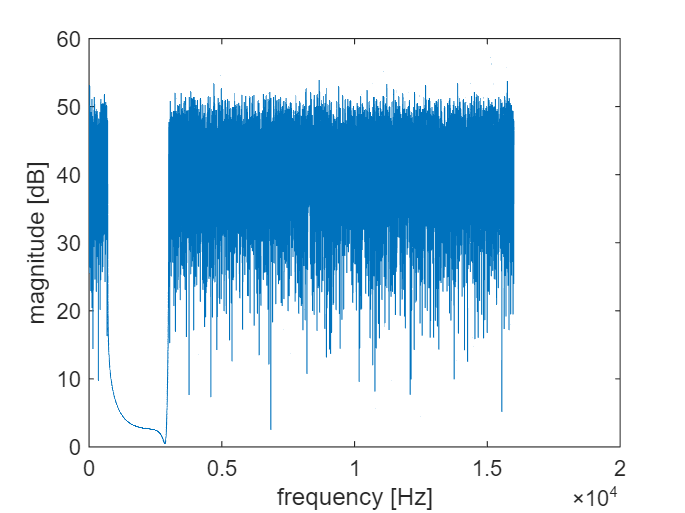





tot2 = fftfilt(sig,filter);

freq_totdft2 = fft(tot2);
freq_totdft2 = freq_totdft2(1:floor(N/2+1));
magn2 = abs(freq_totdft2);

figure;
title('filtered signal')
plot((0:2*fs/N:fs),mag2db(magn2))
ylabel('magnitude [dB]')
xlabel('frequency [Hz]')